# SIO221A

# Problem Week 5

# Aoming Yu

**“I certify that this represents my own work and that I have not worked with classmates or other individuals to complete this assignment.” **

clear 
close all

## 1. Make a preliminary assessment of the data. 

First, plot time series of the total wind speed (“WSPD”), zonal wind (“UWND”), and meridional wind (“VWND”). What is the time interval between data points? What is the time gap between the data files? How are gaps in the data handled? Since there are some gaps in the data, for the rest of this problem set, you will need to fill the gaps. Fill the gaps in each record by linear interpolation. (You can do this with the Matlab function interp1 or xarray.interpolate na in python.) Do not try to interpolate across the gaps between the 3 records, since the gaps are several hours long.

WSPD15 = ncread('OS_T8S110W_DM134A-20150425_D_WIND_10min.nc','WSPD');
WSPD16 = ncread('OS_T8S110W_DM183A-20160321_D_WIND_10min.nc','WSPD');
WSPD17 = ncread('OS_T8S110W_DM231A-20170606_D_WIND_10min.nc','WSPD');

UWND15 = ncread('OS_T8S110W_DM134A-20150425_D_WIND_10min.nc','UWND');
UWND16 = ncread('OS_T8S110W_DM183A-20160321_D_WIND_10min.nc','UWND');
UWND17 = ncread('OS_T8S110W_DM231A-20170606_D_WIND_10min.nc','UWND');

VWND15 = ncread('OS_T8S110W_DM134A-20150425_D_WIND_10min.nc','VWND');
VWND16 = ncread('OS_T8S110W_DM183A-20160321_D_WIND_10min.nc','VWND');
VWND17 = ncread('OS_T8S110W_DM231A-20170606_D_WIND_10min.nc','VWND');

TIME15 = ncread('OS_T8S110W_DM134A-20150425_D_WIND_10min.nc','TIME');
TIME16 = ncread('OS_T8S110W_DM183A-20160321_D_WIND_10min.nc','TIME');
TIME17 = ncread('OS_T8S110W_DM231A-20170606_D_WIND_10min.nc','TIME');

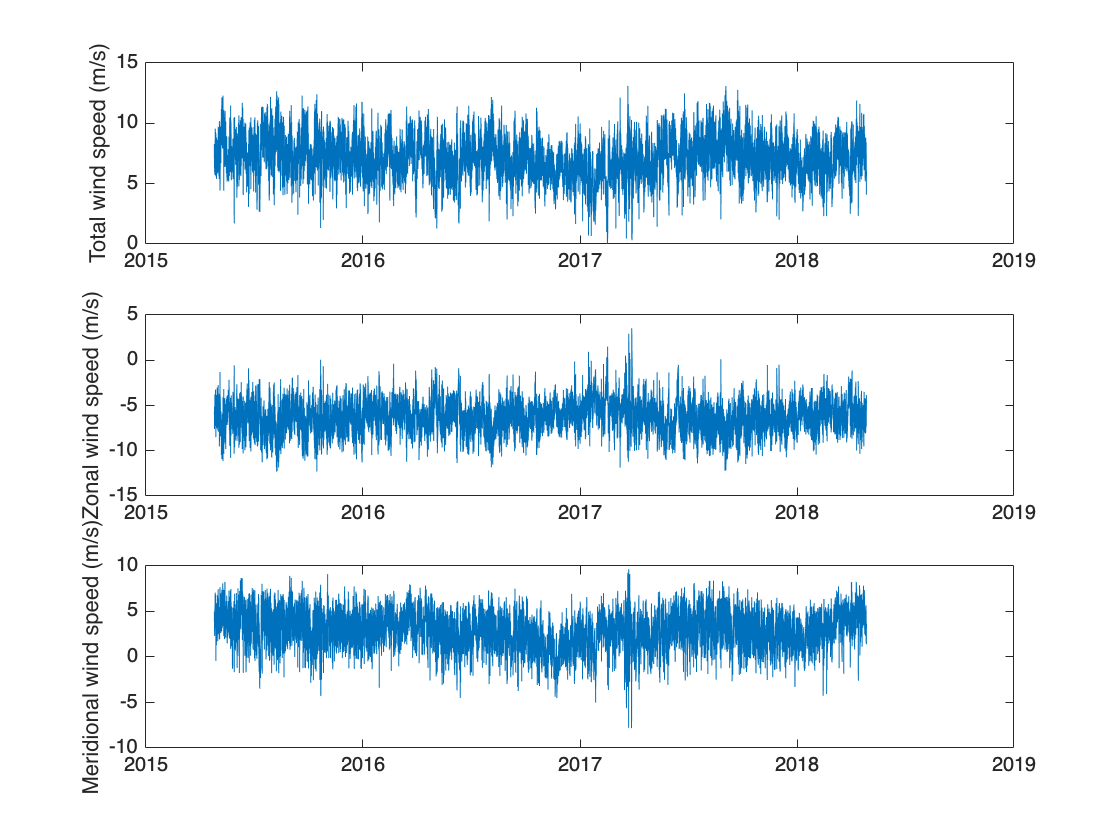

TIME = [TIME15; TIME16; TIME17]+datenum('1950-01-01 00:00:00', 'yyyy-mm-dd HH:MM:SS');
WSPD = [WSPD15 WSPD16 WSPD17];
UWND = [UWND15 UWND16 UWND17];
VWND = [VWND15 VWND16 VWND17];

figure()
subplot(311)
plot(TIME, WSPD)
ylabel('Total wind speed (m/s)')
datetick('x','yyyy')

subplot(312)
plot(TIME, UWND)
ylabel('Zonal wind speed (m/s)')
datetick('x','yyyy')

subplot(313)
plot(TIME, VWND)
ylabel('Meridional wind speed (m/s)')
datetick('x','yyyy')

time_interval = diff(datetime(TIME,'ConvertFrom','datenum'))

time_interval = 157870×1 duration array
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00
   00:10:00


 Time interval between data points is 10 minutes.

threshold = 1/86400*(10*60);
idx = find(time_interval > threshold);
time_interval(idx)

ans = 2×1 duration array
   09:30:00
   22:10:00


The time gap between the data files are 9 hours 30 minutes (2016) and 22 hours 10 minutes (2017)

The gaps in the data are shown as NaNs.						

%Fill gaps
find(isnan(WSPD));
WSPD15_i = fillmissing(WSPD15,'linear');
WSPD16_i = fillmissing(WSPD16,'linear');
WSPD17_i = fillmissing(WSPD17,'linear');

UWND15_i = fillmissing(UWND15,'linear');
UWND16_i = fillmissing(UWND16,'linear');
UWND17_i = fillmissing(UWND17,'linear');

VWND15_i = fillmissing(VWND15,'linear');
VWND16_i = fillmissing(VWND16,'linear');
VWND17_i = fillmissing(VWND17,'linear');

## 2. Segment the data

into 60-day segments with 50% overlap. How many segments do you have for each of the data files? How many points are in each segment? Determine the frequencies (in cycles per day) that you will be able to analyze when you Fourier transform the data. 	

n = 6*24*60;
WSPD15_s = buffer(WSPD15_i,n,0.5*n);
WSPD15_s = WSPD15_s(:,2:end)

WSPD15_s =     7.4700    6.8600    9.3700    9.7900    7.2343    8.7300    8.4100    9.5700    7.7900    5.9600    7.4800
    7.7500    7.2300    8.9400   10.0300    7.1700    8.3100    7.9900    9.4300    8.2100    6.0200    7.1200
    8.1400    7.0900    9.0200   10.4200    6.8300    8.1700    7.7200    9.6000    7.5200    5.9000    7.0900
    7.6000    7.5100    8.9800    9.5600    7.0900    7.9800    8.5100    9.0900    7.7300    6.8200    7.0700
    7.7000    7.3200    8.6500    9.8800    7.1500    8.0900    8.5000    8.3900    8.4200    6.9500    6.8000
    8.2600    7.4100    8.8200    9.1400    6.8700    8.4600    8.5400    8.2900    7.4100    6.3400    7.2300
    7.8400    7.7800    9.0700   10.0800    6.4400    9.0200    8.3000    9.1400    7.2700    6.4900    7.3800
    8.2100    7.3700    9.3000    9.6900    6.5700    8.0900    8.9200    8.7400    7.2300    6.5700    6.9900
    7.7700    7.2100    9.6300    9.7400    6.9400    7.8000    8.8400    9.4900    7.4300    6.4300 

WSPD16_s = buffer(WSPD16_i,n,0.5*n);
WSPD16_s = WSPD16_s(:,2:end)

WSPD16_s =     7.7200    8.6200    6.8900    6.2200    5.8100    6.6800    5.5900    5.2200    6.4900    5.2200    6.4600    2.7200    4.9900    7.5400
    7.9500    8.1000    6.3100    7.0400    5.5700    7.1900    5.7400    5.4200    6.7200    5.3600    7.1300    3.1200    4.6500    6.4300
    7.7500    8.8000    7.1200    6.2000    5.1800    7.4300    5.9400    4.9100    6.4500    5.9900    6.5700    3.5300    4.6800    7.2400
    8.0000    9.6600    7.1900    6.7400    4.7200    7.8900    5.6900    5.4200    6.9400    5.9300    6.3000    3.3500    5.1600    7.9000
    8.1200    9.3800    6.7100    7.8000    4.3400    7.7100    5.9700    5.2700    7.1900    5.7500    6.7100    3.3600    4.7100    7.5000
    8.3200    9.7500    6.8000    7.3300    4.9600    7.9300    5.6900    4.9200    7.5900    5.6500    6.9000    3.0000    5.0100    7.0800
    8.3900    9.3900    7.7000    7.9600    5.0400    8.2300    5.5300    6.1800    6.9500    5.9400    7.0300    3.2000    4.8200    7.2700
  

WSPD17_s = buffer(WSPD17_i,n,0.5*n);
WSPD17_s = WSPD17_s(:,2:end)

WSPD17_s =     8.6600    7.2700    8.4100    8.6100    7.7800    7.1900    7.1400    7.2600    5.9600    7.8100
    8.4400    7.1300    9.1000    7.5700    7.8300    7.4800    7.5600    7.1100    6.5900    7.4300
    8.5800    7.0500    9.2000    7.2200    8.0000    7.3500    6.7900    7.0500    4.7500    7.5000
    8.3700    7.2900    8.6800    8.4100    7.9100    6.7100    7.5600    7.1600    4.9600    7.3600
    8.4300    6.9100    9.7700   11.0100    8.4100    7.0200    7.4400    6.4200    6.9600    7.9700
    9.6600    7.0300    8.7500    7.7100    8.1200    7.2000    7.3700    6.9000    7.2000    7.4700
    8.7300    6.8900    8.8500    6.8800    7.3500    7.0600    7.5100    7.0000    6.7000    7.7100
    7.7800    7.2100    9.0400    7.1000    7.3700    6.8300    6.8300    5.9300    6.9000    7.5100
    7.3900    6.5000    9.3300    7.2100    8.1300    6.9400    7.5000    5.9900    7.8000    7.4500
    8.7100    6.4300    9.0600    6.7900    7.5500    7.1600    7.9900    5.3000

2015 data have 11 segment. 

2016 data have 14 segment. 

2017 data have 10 segment. 

There are 8640 points in each segment.

dt = 10/(60*24);
fn = 1/(2*dt)

fn = 72

N = length(WSPD15_s(:,1));
T = dt*N;
df = 1/T

df = 0.0167

f = 0:df:fn;

frequency vector goes from 0.0167 to 72 cycles per day.

## 3. Compute and plot spectra using 3 different approaches, for the 2015 wind speed record only. 

Compute the spectrum from the raw data, from the detrended data, and from the detrended data with a Hanning window applied. How does detrending and windowing alter the spectrum in this case?

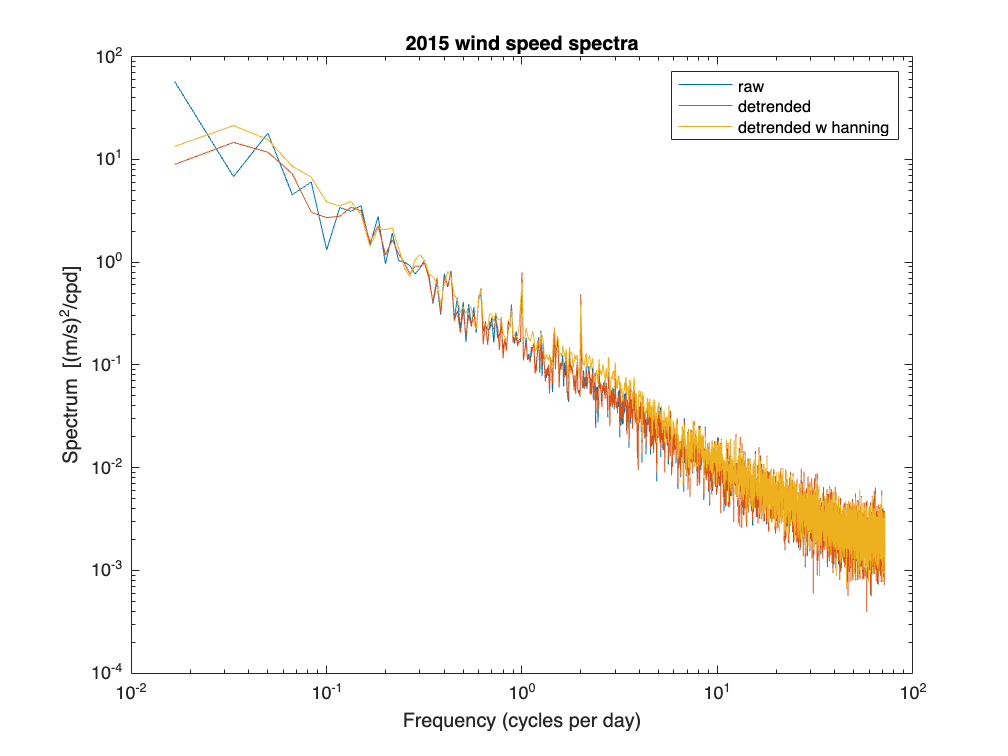

%Raw
amp_r = spec(WSPD15_s);
figure()
loglog(f,amp_r)
hold on

%Detrend
WSPD15_s_d=detrend(WSPD15_s);
amp_d = spec(WSPD15_s_d);

loglog(f,amp_d)

%Hanning
hann_w = sqrt(8/3).*hanning(n);
WSPD15_s_dhan=WSPD15_s_d.*hann_w;
amp_dhan = spec(WSPD15_s_dhan);

loglog(f,amp_dhan)

xlabel('Frequency (cycles per day)')
ylabel('Spectrum [(m/s)^2/cpd]')
title('2015 wind speed spectra')

legend('raw','detrended','detrended w hanning')

Detrending makes the lower frequencies smoother. Detrending with hanning window makes the spectrum slightly less noisy than the raw and detrended data at higher frequency.

## 4. Add uncertainty estimates to the 2015 wind speed spectra. 

Indicate whether you think the uncertainty should differ for the 3 cases.

%𝜈=2𝑛  (two times segments number) degrees of freedom
nu = 11*2 

nu = 22

err_low = nu/chi2inv(1-.05/2,nu)

err_low = 0.5981

err_high = nu/chi2inv(.05/2,nu)

err_high = 2.0032

%With windowing, overlapping by 50% will recover about 90% of the stability lost due to tapering
nu_w = 11*2*0.9

nu_w = 19.8000

err_low_w = nu_w/chi2inv(1-.05/2,nu_w)

err_low_w = 0.5840

err_high_w = nu_w/chi2inv(.05/2,nu_w)

err_high_w = 2.0945

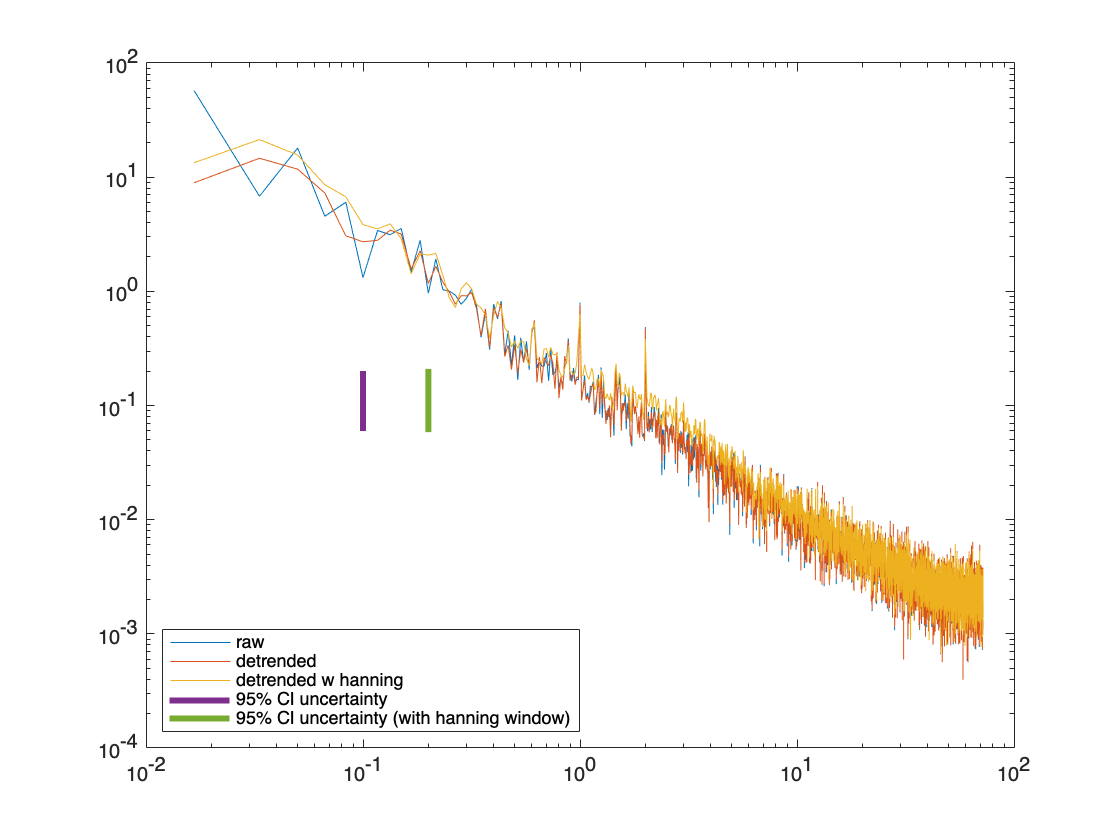

figure()
loglog(f,amp_r)
hold on
loglog(f,amp_d)
loglog(f,amp_dhan)

%set the frequency f and the amplitude A, so that the error bar ends up positioned in a convenient spot on the plot
semilogy([0.1 0.1],[err_low err_high].*0.1,LineWidth=3);
semilogy([0.2 0.2],[err_low_w err_high_w].*0.1,LineWidth=3);
legend('raw','detrended','detrended w hanning','95% CI uncertainty','95% CI uncertainty (with hanning window)',location='southwest')

Uncertainties for raw and detrended data are the same because of the same degrees of freedom. Detrended data with Hanning window applied has different uncertainty (slightly bigger). With windowing, overlapping by 50% will recover about 90% of the stability lost due to tapering (lower degrees of freedom).

## 5. Compute the wind speed spectrum using data from all three data files. 

Do this just using the detrended and Hanning-windowed records. Be sure to compute the uncertainty estimate. Overlay the multi-year spectrum over the 2015 spectrum you computed earlier. How do they differ? Why? Can the differences be explained by differences in the uncertainties?

hann_w = sqrt(8/3).*hanning(n);
WSPD15_s_dhan=WSPD15_s_d.*hann_w;
amp_dhan = spec(WSPD15_s_dhan);

figure()
loglog(f,amp_dhan)
hold on

WSPD_s = [WSPD15_s WSPD16_s WSPD17_s];
WSPD_s_d=detrend(WSPD_s);
WSPD_s_dhan=WSPD_s_d.*hann_w;
AMP_dhan = spec(WSPD_s_dhan);

loglog(f,AMP_dhan)

xlabel('Frequency (cycles per day)')
ylabel('Spectrum [(m/s)^2/cpd]')
title('2015 wind speed spectra vs Multi-year wind speed spectra')

%𝜈=2𝑛  (two times segments number) degrees of freedom
nu = 11*2*0.9

nu = 19.8000

err_low = nu/chi2inv(1-.05/2,nu)

err_low = 0.5840

err_high = nu/chi2inv(.05/2,nu)

err_high = 2.0945

%multi-year
nu_m = (11+14+10)*2*0.9

nu_m = 63

err_low_m = nu_m/chi2inv(1-.05/2,nu_m)

err_low_m = 0.7256

err_high_m= nu_m/chi2inv(.05/2,nu_m)

err_high_m = 1.4668

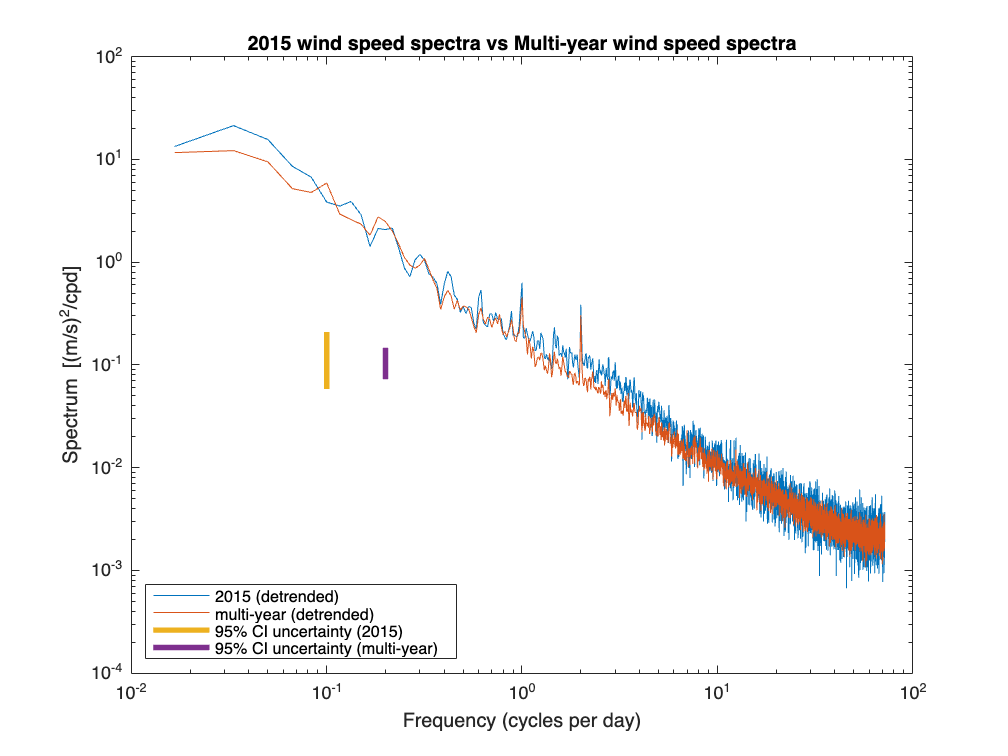

semilogy([0.1 0.1],[err_low err_high]*0.1,LineWidth=3);
semilogy([0.2 0.2],[err_low_m err_high_m]*0.1,LineWidth=3);
legend('2015 (detrended)','multi-year (detrended)','95% CI uncertainty (2015)','95% CI uncertainty (multi-year)',location='southwest')

The multi-year spectra is less noisy compared to the 2015 spectra at higher frequency since the segments number is larger. Because of this, the uncertainty for multi-year spectra is smaller than 2015 spectra uncertainty. More segments lead to a higher degrees of freedom.

## 6. Compare the spectra for wind speed, zonal wind, and meridional wind.

Use all 3 data files, and be sure to detrend and Hanning window. Examine the peaks at the diurnal and semi-diurnal frequencies. How do they differ? Are the differences statistically significant? What do you hypothesize might account for differences?

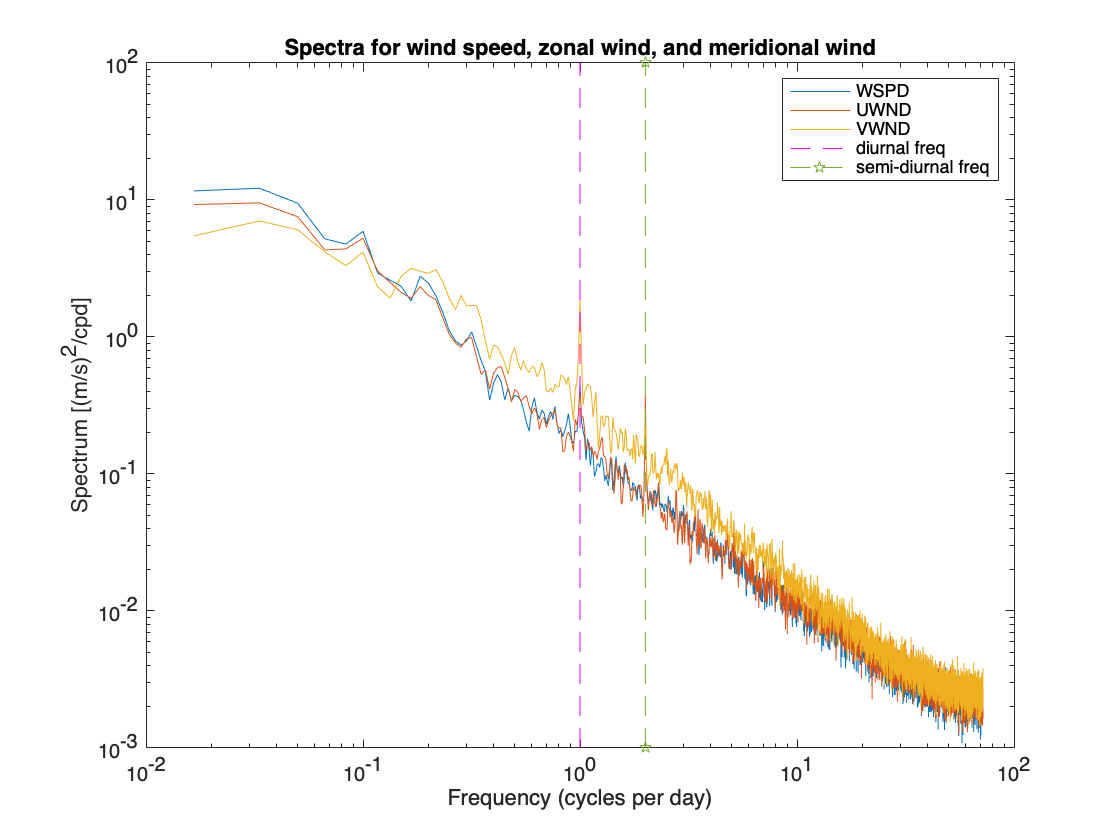

figure()
loglog(f,AMP_dhan)
hold on

%zonal wind (UWND)
UWND_s = seg(UWND15_i,UWND16_i,UWND17_i);
UWND_s_d=detrend(UWND_s);
UWND_s_dhan=UWND_s_d.*hann_w;
AMP_U_dhan = spec(UWND_s_dhan);

loglog(f,AMP_U_dhan)

%meridional wind (VWND)
VWND_s = seg(VWND15_i,VWND16_i,VWND17_i);
VWND_s_d=detrend(VWND_s);
VWND_s_dhan=VWND_s_d.*hann_w;
AMP_V_dhan = spec(VWND_s_dhan);

loglog(f,AMP_V_dhan)

%peaks at the diurnal and semi-diurnal frequencies
loglog([1 1],[10^-3 10^2],'m--')
loglog([2 2],[10^-3 10^2],'p--')

xlabel('Frequency (cycles per day)')
ylabel('Spectrum [(m/s)^2/cpd]')
title('Spectra for wind speed, zonal wind, and meridional wind')
legend('WSPD','UWND','VWND','diurnal freq','semi-diurnal freq')

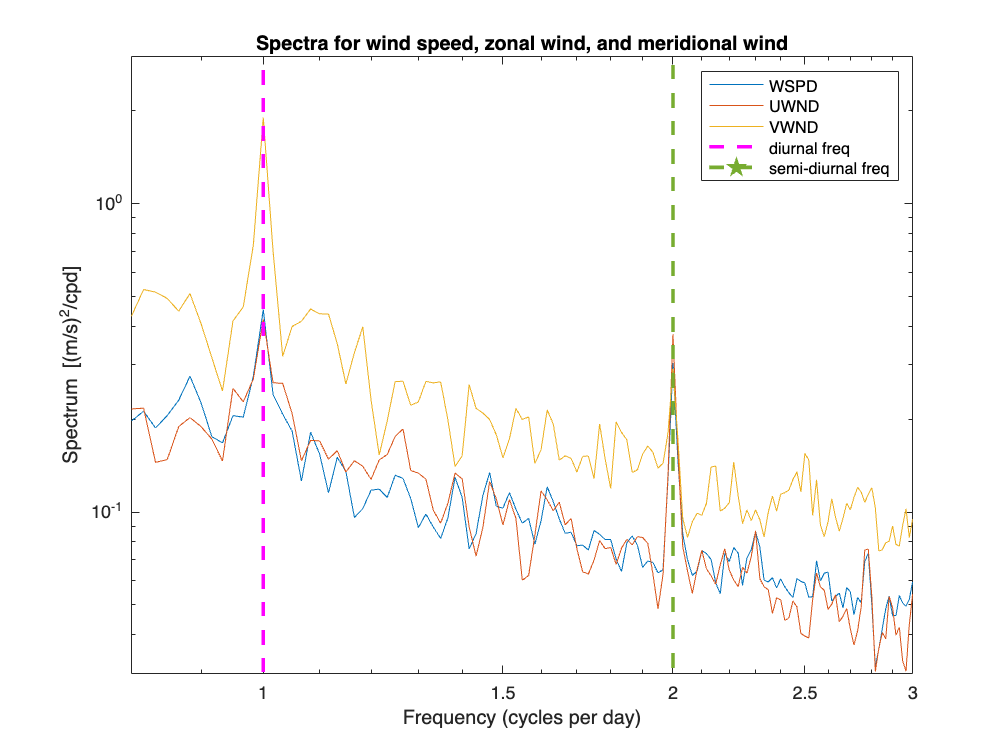

figure()
loglog(f,AMP_dhan)
hold on
loglog(f,AMP_U_dhan)
loglog(f,AMP_V_dhan)
loglog([1 1],[10^-3 10^2],'m--',linewidth=2)
loglog([2 2],[10^-3 10^2],'p--',linewidth=2)
xlim([0.8 3])
ylim([0.03 3])

xlabel('Frequency (cycles per day)')
ylabel('Spectrum [(m/s)^2/cpd]')
title('Spectra for wind speed, zonal wind, and meridional wind')
legend('WSPD','UWND','VWND','diurnal freq','semi-diurnal freq')

The meridional wind speed spectrum (VWND) is higher than the total wind speed spectrum (WSPD) and zonal wind speed spectrum (UWND). At diurnal frequency, VWND spectrum is much larger than WSPD and UWND spectrums. At semi-diurnla frequency, the three spectrums have the same amplitude. The meridional wind has a stronger diurnal pattern, maybe has to do with seasonality (not sure).